# Protocol

*follow*[* these steps *](matlab:open('./matlab_DL_link.pdf'))*for connecting Matlab to Biometrics Datalink*

- Launch the Biometrics Datalink

- The Biometrics Application MUST have file save mode turned off

- Run [DatalogInit.m](matlab:open('..\MATLAB\DataLogInit.m')) 

%DataLogInit

        4. Setup a sensor and record it in the Biometrics Application

        5. Select Channel and set parameters

        6. Run [getDataFromChannel.m](matlab:open('./getDataFromChannel.m')) to extract real time data

%getDataFromChannel(channel,sampleRate,numberOfValues);

         7. Run MEP detection to detect MEP in real time by using functions in the MEP folder

### **IMPORTANT : The Data can only be acquired for 50000 samples (50s if 1000 sf) before the data overflows. After 50s STOP and START the EMG recording.**

Remarks : 

- You cannot send twice the same samples so NO OVERLAPPING WINDOWS. Practically this means if you take windows of 2s, when you press the first time 'getDataFromChannel' you will get the 2s window. However if you press a second time on 'getDataFromChannel' before waiting 2s, you will only get the remaining. Example: for a 2s window, sending data request 1.5s after the first request will only give you a 1.5s window since 0.5s overlap with the previous window.

- In the same lines, if your window is bigger than the elapsed time from the start of the recording you will only get the available samples. Example : for a 2s window, press START at t = 0, sending data request after 1s will only get you a 1s window.

# Imports

% for stimulator
folder = 'NewBoardTest';
addpath(genpath(folder));

% 
ComPort        = 'COM28';
Baudrate       = 115200*8;   %921600
 
run('OpenComPort.m'); %

clc;

addpath 'MEP_Detection' %to have the MEP functions
addpath 'LINK' %to have the Matlab-DataLink connection functions

% Specify the folder path to save the data
folderPath = 'DATA\20march\';

% Check if the folder exists, if not, create it
if ~exist(folderPath, 'dir')
    mkdir(folderPath);
end

# Set Parameters

With the following parameters we have a first pulse of 10ms, interpulse interval of 50ms, interframe interval of 5s.

selectedChannels = {0,1,2,3,4,5}; % channel to record from, multiple channels will be used later. Channel 0 here is channel 1 on BIOMETRICS
muscleLocations = {'distal','distal','distal','distal','proximal','proximal'}; % for each channel put the corresponding distal or proximal
updateRate = 0.01; %in s
sf = 1000; %sampling frequency of channel acquisition
%numberOfValues = 680; %windows of 680ms (-30ms before, +650ms after first stimulus)

values_before_stim = 1000; %100ms before the stimulation
values_after_stim = 1000; %1s after the stimulation
numberOfValues = values_before_stim+values_after_stim; 
disp(numberOfValues);

        2000





% EMG preprocessing
plot_chs = false;
bool_plot_PSD = false;
selected_filters = 3;
paper_nb = 1;



SetSingleChanState(s, 0, 1, 1, 0); %should turn red
%SetSingleChanState(s, 1, 1, 1, 0);


% Stimulation Variables
pulse_width = uint32(490); % us --- Fixed --- Remember this is half of the duration of a bi-phasic pulse
pulse_width_1pulse = uint32(1000); % us --- Fixed --- The total duration of a burster (made of several short bi-phasic pulses)
N_pulse_repetition = 2;     % --- Insert 1 to Single Pulse (SP)-  2 to Double Pulse (DP) --- the number of inner bi-phasic pulses in a burster.   
interpulse_duration = uint32(50 *1000); % us - ms --- for Double pulse. Usually between 35-100ms --- time between two bi-phasic pulses. 
pulse_deadtime = uint32(20);        % us - --- Fixed ---  20 is the minimum
interframe_duration = uint32( 5000000 ); % us - s 
%burst_interframe_duration = uint32( 1e6 * 1/STIMULATION_FREQ - ...    % --- Not used for PRM reflex --- 
%                                       (burst_inner_pulse_repetition * (2 * burst_single_phase_pulse_duration + burst_pulse_deadtime) ) ... % the total duration of the bi-phasic pulses including deadtime
%                                       ) ; % us. This is the time between two bursters. - Not necessary for SP and DP
current =  70; % mA
max_current = 10; % mA

% MEP detection
bool_plot_MEP = false;
bool_colour_response = false;

# Prepare Stimulator parameters

SetSingleChanAllParam(s, 0, ...
                        pulse_width, ...    % pulseDurationUS
                        pulse_deadtime, ...                 % deadTimeUS
                        interpulse_duration, ...            % interpulseDurationUS
                        interframe_duration, ...            % interframeDurationUS
                        N_pulse_repetition, ...         % numberOfPulsesPerFrame
                        current ...               % IAmplitude in mA
                        );

%% Enable Trigger Mode
SetSingleChanSingleParam_v2(s, 0, 7, 0) % Trigger mode (7), Output
SetSingleChanState(s, 0, 1, 0, 0) %  Output disabled

# Real time MEP detection

In this part we aim to detect in real time the Muscle Evoked Potentials at each stimulation. To do so, we perform 3 repetitions at each current value, increasing the current by steps of 5mA. We collect the data, preprocess it and analyze the response.

%% Enable Trigger Mode
SetSingleChanSingleParam_v2(s, 0, 7, 0) % Trigger mode (7), Output
SetSingleChanState(s, 0, 1, 0, 0) %  Output disabled 

EMG_stim =[];
EMG_data = [];
EMG_trigger = [];
SetSingleChanState(s, 0, 1, 1, 1);

start_time = tic;


% The following section aims to find the T_0
current = 15; % small comfortable current to only see artifact
not_found = true;
SetSingleChanSingleParam(s, 0, 6, current)

while not_found
    pause(4);
    loop_time = tic;
    emg_stim = getDataFromChannel(selectedChannels{1},sf,4000); % collect data    
    
    [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_stim))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess
    [not_found, time] = StimPulseDetection(EMG_preprocessed,interpulse_duration,sf);
    EMG_stim =[EMG_stim;double(emg_stim)'];
    elapsed_time = toc(loop_time);
end

2 peaks found
T 0
        2191




time_step_1 = toc(start_time);
disp("FOUND after :");

FOUND after :


disp(time_step_1);

    4.0159




disp("waiting for :");

waiting for :


disp(time-elapsed_time);

    3.1851



disp("elapsed_time from loop");

elapsed_time from loop


disp(elapsed_time);

    0.0059



pause(time-elapsed_time);

disp("taking interval emg at time : ");
disp(toc(start_time));

emg_interval= getDataFromChannel(selectedChannels{1},sf,15000); % collect data a enlever pour apres
[not_found, time] = StimPulseDetection((double(emg_interval))',interpulse_duration,sf);
n_samples = length(emg_interval(1,:));

STARTING CURRENT LOOP at time : 


    7.2088



2 peaks found
T 0
        3237



disp("extra time :")

extra time :


disp(n_samples-(n_samples - (5 * sf - time * sf)));

        1463





disp("STARTING CURRENT LOOP at time : ");

STARTING CURRENT LOOP at time : 


disp(toc(start_time));

    7.2159



Repetition: 1


Current: 35


   100



Response for current 35 and repetition 1: no response


Processing time: 0.0409 seconds


Repetition: 2


Current: 35


   100



Response for current 35 and repetition 2: no response


Processing time: 0.0431 seconds


Repetition: 3


Current: 35


   100



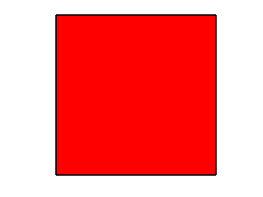

Response for current 35 and repetition 3: no response


Processing time: 0.0372 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



for j = 1: 1    % Need to be increase if 
    current =  30 + j*5; % mA 
    SetSingleChanSingleParam(s, 0, 6, current)
    
    for i = 1: 3  % Number of repetitions
        % Enable Output
        %pause(values_after_stim/sf) %A RECHANGER A 650 take window of 680ms after 650ms of stimulation (it will take 650ms for the first run since we won't have 680 available values)
        pause(4)
        numberOfValues = 5000;
        % collect EMG data and process it
        tic; % start timer
        
        disp(['Repetition: ', num2str(i)]);
        disp(['Current: ', num2str(current)]);
        emg_data = getDataFromChannel(selectedChannels{1},sf,numberOfValues); % collect data
        emg_trigger= getDataFromChannel(8,sf,numberOfValues); % collect data        

        [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_data))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess
        
        EMG_data =[EMG_data;double(emg_data)'];
        %EMG_trigger = [EMG_trigger;emg_trigger];

        response = ActionPotDetectDoublePulse(muscleLocations{1},EMG_preprocessed,sf, interpulse_duration,values_before_stim,norm_factor_afterfilter,bool_plot_MEP,bool_colour_response); %find response 'no response', 'MEP reflex', 'M-wave', 'invalid'
        
        fprintf('Response for current %d and repetition %d: %s\n', current, i, response);

        % Save the data in the 'DATA' folder
        filename = fullfile(folderPath, sprintf('emg_current%d_repetition%d_%sswindow_100interpulse.mat', current,i,num2str(numberOfValues/sf, '%.1f')));
        save(filename, 'emg_data');

        elapsed_time = toc; % stop timer
        fprintf('Processing time: %.4f seconds\n', elapsed_time);

        %pause(5-values_after_stim/sf-elapsed_time); %take into account processing time for interframe interval (4.35)
        pause(5-4-elapsed_time);
    end
    disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")
    
end


disp(numberOfValues);

        5000



SetSingleChanState(s, 0, 1, 0, 0);


%Official

EMG_stim =[];

   100000



EMG_data = [];
EMG_trigger = [];
all_responses = {}; % jxi array of responses
folderPath = 'DATA\20march\black2\45-50-50ip';


SetSingleChanState(s, 0, 1, 1, 0); % 
pause(2)
SetSingleChanState(s, 0, 1, 1, 1);

start_time = tic;


% The following section aims to find the T_0
current = 15; % small comfortable current to only see artifact
not_found = true;
SetSingleChanSingleParam(s, 0, 6, current)
j =0;
emg_removed = getDataFromChannel(selectedChannels{6},sf,40000); % remove available samples before recording

while not_found
    j = j+1;
    pause(4);
    loop_time = tic;
    emg_stim = getDataFromChannel(selectedChannels{6},sf,4000); % collect data    

    [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_stim))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess
    [not_found, time,t_0] = StimPulseDetection2(EMG_preprocessed,interpulse_duration,sf);
    EMG_stim =[EMG_stim;double(emg_stim)'];
    elapsed_time = toc(loop_time);
end
first = toc(start_time);
disp("TIME AT BEGINNING FOR LOOP ")

    "stim artifact found at t : "    "1661"

2 peaks found


disp(first)
theoretical_elapsed_time = 4*j;

TIME AT BEGINNING FOR LOOP 


offset = 1000+first-theoretical_elapsed_time;

    4.0372



Repetition: 1


Current: 45


getData returned 0 from channel 8


Getting current at time : 9.0452


Looking at pulse at time t_0 = : 2710.0794


INTERPULSE FIRST
   50000

    "NOISE LEVEL : "    "1.1341"

    8.2696

CONDITION DIS - IP  : 
   0

    "NOISE LEVEL : "    "1.1341"

    7.8115

CONDITION DIS - IP  : 
   1

VALID
     2

    "NOISE LEVEL : "    "1.1341"

    0.4581

CONDITION DIS - IP  : 
   0

    "FOUND STIMULATION ARTIFACT AT : "    "2631"

BLANKED
SIZE
        5000           1

    "TOP LOCATION :"    "2722"

SEQRCH
        2702

   2742

INTERPULSE
   50



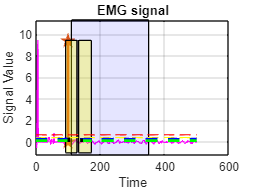

Response for current 45 and repetition 1: no response


Processing time: 0.0774 seconds


Repetition: 2


Current: 45


getData returned 0 from channel 8


Getting current at time : 14.1268


Looking at pulse at time t_0 = : 2759.2035


INTERPULSE FIRST
   50000

    "NOISE LEVEL : "    "1.2457"

    7.1947

CONDITION DIS - IP  : 
   0

    "NOISE LEVEL : "    "1.2457"

    6.9610

CONDITION DIS - IP  : 
   1

VALID
     2

    "NOISE LEVEL : "    "1.2457"

    0.2338

CONDITION DIS - IP  : 
   0

    "FOUND STIMULATION ARTIFACT AT : "    "2630"

BLANKED
SIZE
        5000           1

    "TOP LOCATION :"    "2897"

SEQRCH
        2877

   2917

INTERPULSE
   50



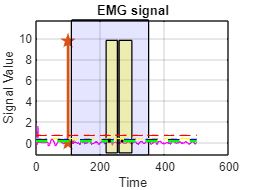

Response for current 45 and repetition 2: no response


Processing time: 0.0832 seconds


Repetition: 3


Current: 45


getData returned 0 from channel 8


Getting current at time : 19.2223


Looking at pulse at time t_0 = : 2808.4214


INTERPULSE FIRST
   50000

    "NOISE LEVEL : "    "1.1796"

    7.6863

CONDITION DIS - IP  : 
   0

    "NOISE LEVEL : "    "1.1796"

    7.2766

CONDITION DIS - IP  : 
   1

VALID
     2

    "NOISE LEVEL : "    "1.1796"

    0.4097

CONDITION DIS - IP  : 
   0

    "FOUND STIMULATION ARTIFACT AT : "    "2628"

BLANKED
SIZE
        5000           1

    "TOP LOCATION :"    "2833"

SEQRCH
        2813

   2853

INTERPULSE
   50



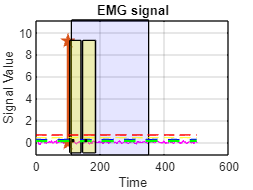

Response for current 45 and repetition 3: no response


Processing time: 0.0733 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Repetition: 1


Current: 50


getData returned 0 from channel 8


Getting current at time : 24.3009


Looking at pulse at time t_0 = : 2710.7191


INTERPULSE FIRST
   50000

    "NOISE LEVEL : "    "1.2866"

    7.5288

CONDITION DIS - IP  : 
   0

    "NOISE LEVEL : "    "1.2866"

    6.2378

CONDITION DIS - IP  : 
   1

    "NOISE LEVEL : "    "1.2866"

    1.2910

CONDITION DIS - IP  : 
   0

NO STIMULATION ARTIFACT FOUND
SIZE
        5000           1

    "TOP LOCATION :"    "2729"

SEQRCH
        2709

   2749

INTERPULSE
   50



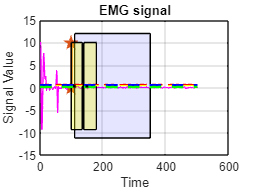

Response for current 50 and repetition 1: presumed M-wave


Processing time: 0.0691 seconds


Repetition: 2


Current: 50


getData returned 0 from channel 8


Getting current at time : 29.3743


Looking at pulse at time t_0 = : 2760.0896


INTERPULSE FIRST
   50000

    "NOISE LEVEL : "    "1.3044"

    7.6635

CONDITION DIS - IP  : 
   0

    "NOISE LEVEL : "    "1.3044"

    5.3301

CONDITION DIS - IP  : 
   1

    "NOISE LEVEL : "    "1.3044"

    2.3334

CONDITION DIS - IP  : 
   0

NO STIMULATION ARTIFACT FOUND
SIZE
        5000           1

    "TOP LOCATION :"    "2839"

SEQRCH
        2819

   2859

INTERPULSE
   50



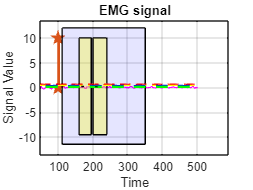

Response for current 50 and repetition 2: no response


Processing time: 0.0800 seconds


Repetition: 3


Current: 50


getData returned 0 from channel 8


Getting current at time : 34.4637


Looking at pulse at time t_0 = : 2809.5488


INTERPULSE FIRST
   50000

    "NOISE LEVEL : "    "1.352"

    6.9701

CONDITION DIS - IP  : 
   0

    "NOISE LEVEL : "    "1.352"

    6.6070

CONDITION DIS - IP  : 
   1

VALID
     2

    "NOISE LEVEL : "    "1.352"

    0.3630

CONDITION DIS - IP  : 
   0

    "FOUND STIMULATION ARTIFACT AT : "    "2624"

BLANKED
SIZE
        5000           1

    "TOP LOCATION :"    "3029"

SEQRCH
        3009

   3049

INTERPULSE
   50



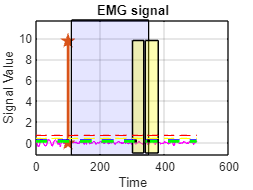

Response for current 50 and repetition 3: no response


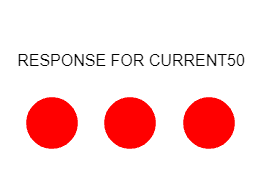

Processing time: 0.0832 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



emg_removed = getDataFromChannel(selectedChannels{2},sf,40000); % remove available samples before recording

for j = 1: 2    % Need to be increase if 
    current =  40 + j*5; % mA 
    SetSingleChanSingleParam(s, 0, 6, current)
    
    rep_response = {};  % Initialize response cell array for each i

    for i = 1: 3  % Number of repetitions
        % Enable Output
        %pause(values_after_stim/sf) %A RECHANGER A 650 take window of 680ms after 650ms of stimulation (it will take 650ms for the first run since we won't have 680 available values)
        pause(5)
        numberOfValues = 5000;
        %collect EMG data and process it
        for_timer = tic; % start timer
        theoretical_elapsed_time = theoretical_elapsed_time+5;
        offset = offset+ toc(start_time)-theoretical_elapsed_time;
        updated_t_0 = t_0 +offset+49*i; %offset is computation time and 49(ms) is the time shift of each window

        disp(['Repetition: ', num2str(i)]);
        disp(['Current: ', num2str(current)]);
        emg_data = getDataFromChannel(selectedChannels{2},sf,numberOfValues); % collect data
        emg_trigger= getDataFromChannel(8,sf,numberOfValues); % collect data        
        disp(['Getting current at time : ', num2str(toc(start_time))]);



        [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_data))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess

        EMG_data =[EMG_data;double(emg_data)'];
        EMG_trigger = [EMG_trigger;emg_trigger];

        % APD SHOULD ONLY TAKE 1 channel!! TO BE CHANGED 
        disp(['Looking at pulse at time t_0 = : ', num2str(updated_t_0)]);
        response = ActionPotDetectDoublePulse3(updated_t_0,muscleLocations{1},EMG_preprocessed,sf, interpulse_duration,norm_factor_afterfilter,true,bool_colour_response,numberOfValues); %find response 'no response', 'MEP reflex', 'M-wave', 'invalid'
        rep_response = [rep_response,response];  

        fprintf('Response for current %d and repetition %d: %s\n', current, i, response);
        plot_response(rep_response,current);
        % Save the data in the 'DATA' folder
        filename = fullfile(folderPath, sprintf('emg_current%d_repetition%d_%sswindow_100interpulse.mat', current,i,num2str(numberOfValues/sf, '%.1f')));
        save(filename, 'emg_data'); % saving raw data

        elapsed_time_loop = toc(for_timer); % stop timer
        fprintf('Processing time: %.4f seconds\n', elapsed_time_loop);

        
    end
    disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")
    
    all_responses = [all_responses; response];  

    
end
disp(['Getting last current at time : ', num2str(toc(start_time))]);
%Soleus_R in real time

emg_data_1 = getDataFromChannel(selectedChannels{1},sf,45000); % collect data Soleus_L

Getting last current at time : 34.5487


emg_data_2 = getDataFromChannel(selectedChannels{3},sf,45000); % collect data TA_R
emg_data_3 = getDataFromChannel(selectedChannels{4},sf,45000); % collect data TA_L
emg_data_4 = getDataFromChannel(selectedChannels{5},sf,45000); % collect data RF_R
emg_data_5 = getDataFromChannel(selectedChannels{6},sf,45000); % collect data RF_L

filename = fullfile(folderPath, 'full_emg_1.mat');
save(filename, 'emg_data_1'); % saving raw data
filename = fullfile(folderPath, 'full_emg_2.mat');
save(filename, 'emg_data_2'); % saving raw data
filename = fullfile(folderPath, 'full_emg_3.mat');
save(filename, 'emg_data_3'); % saving raw data
filename = fullfile(folderPath, 'full_emg_4.mat');
save(filename, 'emg_data_4'); % saving raw data
filename = fullfile(folderPath, 'full_emg_5.mat');
save(filename, 'emg_data_5'); % saving raw data

disp(numberOfValues);
SetSingleChanState(s, 0, 1, 0, 0);

EMG_stim =[];

        5000



EMG_data = [];
EMG_trigger = [];
all_responses = {}; % jxi array of responses


SetSingleChanState(s, 0, 1, 1, 0); % 
pause(2)
SetSingleChanState(s, 0, 1, 1, 1);

start_time = tic;


% The following section aims to find the T_0
current = 15; % small comfortable current to only see artifact
not_found = true;
SetSingleChanSingleParam(s, 0, 6, current)
j =0;
emg_removed = getDataFromChannel(selectedChannels{1},sf,40000); % remove available samples before recording

while not_found
    j = j+1;
    pause(4);
    loop_time = tic;
    emg_stim = getDataFromChannel(selectedChannels{1},sf,4000); % collect data    

    [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_stim))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess
    [not_found, time,t_0] = StimPulseDetection2(EMG_preprocessed,interpulse_duration,sf);
    EMG_stim =[EMG_stim;double(emg_stim)'];
    elapsed_time = toc(loop_time);
end
first = toc(start_time);
disp("TIME AT BEGINNING FOR LOOP ")
disp(first)
theoretical_elapsed_time = 4*j;
offset = 1000+first-theoretical_elapsed_time;
for j = 1: 2    % Need to be increase if 
    current =  60 + j*5; % mA 
    SetSingleChanSingleParam(s, 0, 6, current)
    
    rep_response = {};  % Initialize response cell array for each i

    for i = 1: 3  % Number of repetitions
        % Enable Output
        %pause(values_after_stim/sf) %A RECHANGER A 650 take window of 680ms after 650ms of stimulation (it will take 650ms for the first run since we won't have 680 available values)
        pause(5)
        numberOfValues = 5000;
        %collect EMG data and process it
        for_timer = tic; % start timer
        theoretical_elapsed_time = theoretical_elapsed_time+5;
        offset = offset+ toc(start_time)-theoretical_elapsed_time;
        updated_t_0 = t_0 +offset+49*i; %offset is computation time and 49(ms) is the time shift of each window

        disp(['Repetition: ', num2str(i)]);
        disp(['Current: ', num2str(current)]);
        emg_data = getDataFromChannel(selectedChannels{1},sf,numberOfValues); % collect data
        emg_trigger= getDataFromChannel(8,sf,numberOfValues); % collect data        
        disp(['Getting current at time : ', num2str(toc(start_time))]);



        [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_data))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess

        EMG_data =[EMG_data;double(emg_data)'];
        EMG_trigger = [EMG_trigger;emg_trigger];

        
        % APD SHOULD ONLY TAKE 1 channel!! TO BE CHANGED 
        disp(['Looking at pulse at time t_0 = : ', num2str(updated_t_0)]);
        response = ActionPotDetectDoublePulse3(updated_t_0,muscleLocations{1},EMG_preprocessed,sf, interpulse_duration/1000,norm_factor_afterfilter,bool_plot_MEP,bool_colour_response,numberOfValues); %find response 'no response', 'MEP reflex', 'M-wave', 'invalid'
        rep_response = [rep_response,response];  

        fprintf('Response for current %d and repetition %d: %s\n', current, i, response);
        plot_response(rep_response,current);
        % Save the data in the 'DATA' folder
        filename = fullfile(folderPath, sprintf('emg_current%d_repetition%d_%sswindow_100interpulse.mat', current,i,num2str(numberOfValues/sf, '%.1f')));
        save(filename, 'emg_data'); % saving raw data

        elapsed_time_loop = toc(for_timer); % stop timer
        fprintf('Processing time: %.4f seconds\n', elapsed_time_loop);

        
    end
    disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")
    
    all_responses = [all_responses; response];  

    
end
disp(['Getting last current at time : ', num2str(toc(start_time))]);
%Soleus_R in real time
emg_data_1 = getDataFromChannel(selectedChannels{2},sf,45000); % collect data Soleus_L
emg_data_2 = getDataFromChannel(selectedChannels{3},sf,45000); % collect data TA_R
emg_data_3 = getDataFromChannel(selectedChannels{4},sf,45000); % collect data TA_L
emg_data_4 = getDataFromChannel(selectedChannels{5},sf,45000); % collect data RF_R
emg_data_5 = getDataFromChannel(selectedChannels{6},sf,45000); % collect data RF_L

filename = fullfile(folderPath, 'full_emg_1.mat');
save(filename, 'emg_data_1'); % saving raw data
filename = fullfile(folderPath, 'full_emg_2.mat');
save(filename, 'emg_data_2'); % saving raw data
filename = fullfile(folderPath, 'full_emg_3.mat');
save(filename, 'emg_data_3'); % saving raw data
filename = fullfile(folderPath, 'full_emg_4.mat');
save(filename, 'emg_data_4'); % saving raw data
filename = fullfile(folderPath, 'full_emg_5.mat');
save(filename, 'emg_data_5'); % saving raw data

disp(numberOfValues);
SetSingleChanState(s, 0, 1, 0, 0);